%迭代寻优，预测风化前的状态
clear;clc

table1=readtable("分组.xlsx","VariableNamingRule","preserve","Sheet","铅钡无风化");
table2=readtable("分组.xlsx","VariableNamingRule","preserve","Sheet","铅钡风化");
table3=readtable("分组.xlsx","VariableNamingRule","preserve","Sheet","高钾无风化");
table4=readtable("分组.xlsx","VariableNamingRule","preserve","Sheet","高钾风化");

namelist=table1.Properties.VariableNames(2:end);

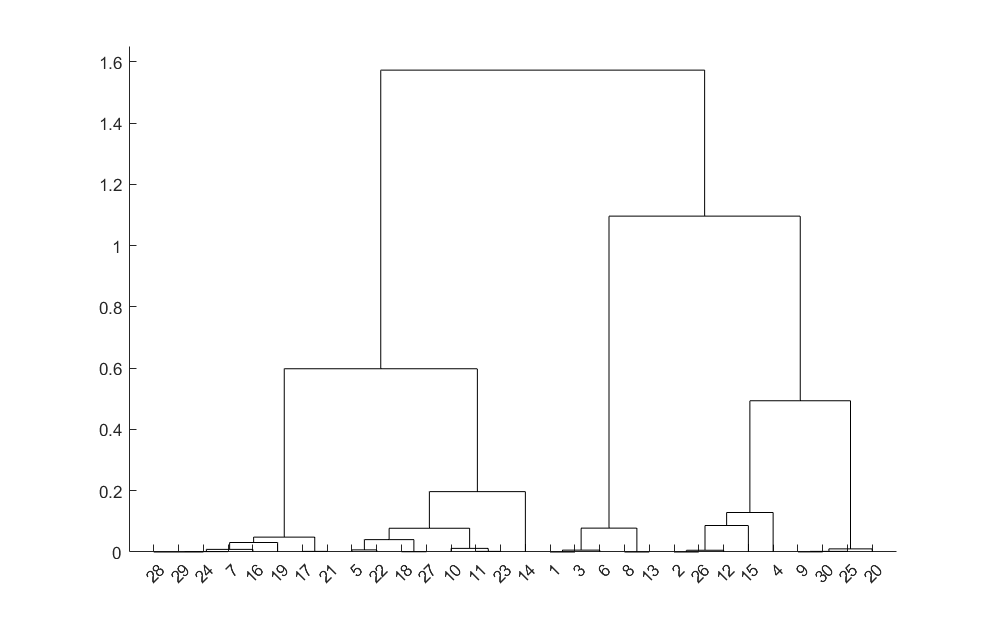

forecast1=table2array(table1(:,2:end));
original1=table2array(table2(:,2:end));
max=size(forecast1);

selectVar=[3 5 12];
result1=[];

for i=1:size(original1,1)
    for k=1:100
        Id1={5};
        next=[];
        a=forecast1(:,selectVar);
        b=zscore(a); % 数据标准化
        d=pdist(b,'correlation'); 
        z=linkage(d,'average'); % 按类平均法聚类
        T=cluster(z,'maxclust',5);
        for n=1:5
            tm=find(T==n);
            tm=reshape(tm,1,length(tm));
            Id1{n}=tm;
        end
        temp=[  mean(forecast1(Id1{1},:),1)
                mean(forecast1(Id1{2},:),1)
                mean(forecast1(Id1{3},:),1) 
                mean(forecast1(Id1{4},:),1)
                mean(forecast1(Id1{5},:),1) ];
        ori=original1(i,:);
        min=1e9;
        idx=1;
        for j=1:size(temp,1)
            c=(ori(:,selectVar)-temp(j,selectVar)).^2;
            d=sqrt(sum(c(:)));
            if d<min
                min=d;
                idx=j;
            end
        end
        %next=[next;min];
        forecast1(max(1)+i,:)=temp(idx,:);
        result1(i,:)=temp(idx,:);
        % 设置平均距离小于0.3时退出循环，就输出视为预测结果
        if min<0.3
            break
        end
    end
end

h=dendrogram(z);
set(h,'Color','k')

k=5;
fprintf("划分成%d类的结果如下:\n",k)

划分成5类的结果如下:


T=cluster(z,'maxclust',k);%划分k类
for i=1:k
    tm=find(T==i);%求第i类的对象
    tm=reshape(tm,1,length(tm));
    fprintf("第%d类的有:%s\n",i,int2str(tm));
end

第1类的有:9  20  25  26  29  30  31  32  33  47  48
第2类的有:2   4  12  15  34  35  41  44
第3类的有:7  16  17  19  21  24  36  39  40  43
第4类的有:5  10  11  14  18  22  23  27  28  37  38  42  45  46  49
第5类的有:1   3   6   8  13


%铅钡玻璃的预测情况
array2table(result1,"VariableNames",namelist)

ans = 26×14 table
    二氧化硅(SiO2)    氧化钠(Na2O)    氧化钾(K2O)    氧化钙(CaO)    氧化镁(MgO)    氧化铝(Al2O3)    氧化铁(Fe2O3)    氧化铜(CuO)    氧化铅(PbO)    氧化钡(BaO)    五氧化二磷(P2O5)    氧化锶(SrO)    氧化锡(SnO2)    二氧化硫(SO2)
    _____________    ___________    __________    __________    __________    ____________    ____________    __________    __________    __________    _______________    __________    ___________    ____________

       62.566            1.32           0.272        1.408          1.17           6.71           0.498          0.942         17.75         4.938            1.18            0.134         0.046              0    
       57.157            1.79         0.14333         1.22             0           5.77         0.77333           1.52        20.917        7.4033            0.55          0.25667             0           1.22    
       57.157            1.79         0.14333         1.22             0           5.77         0.77333           1.52        20.917        7.4033            0.5

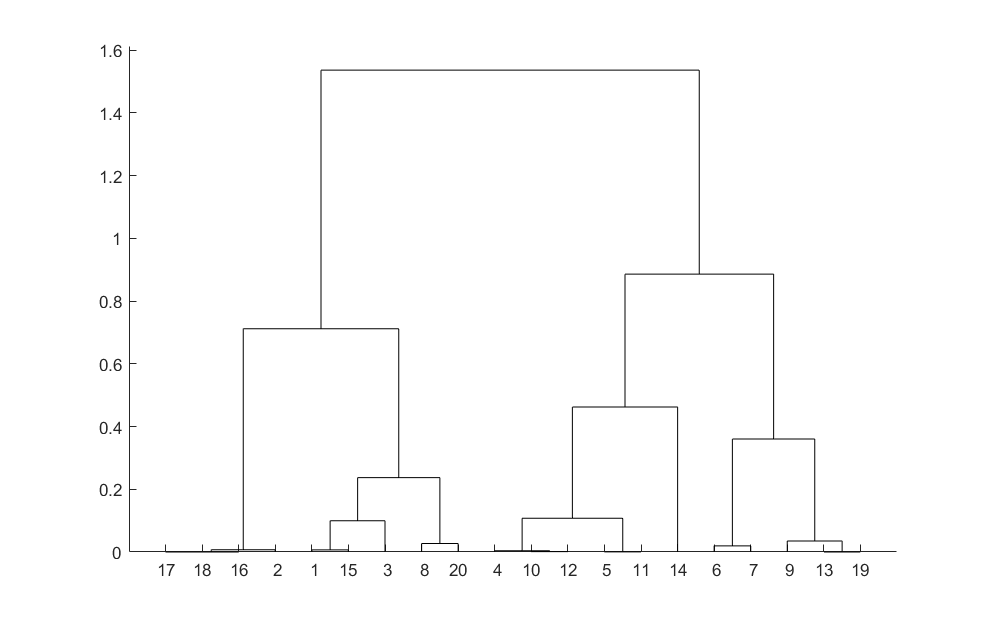

forecast2=table2array(table3(:,2:end));
original2=table2array(table4(:,2:end));
max=size(forecast2);

selectVar=[5 8 11];
result2=[];

for i=1:size(original2,1)
    for k=1:100
        Id2={4};
        next=[];
        a=forecast2(:,selectVar);
        b=zscore(a); % 数据标准化
        d=pdist(b,'correlation'); 
        z=linkage(d,'average'); % 按类平均法聚类
        T=cluster(z,'maxclust',4);
        for n=1:4
            tm=find(T==n);
            tm=reshape(tm,1,length(tm));
            Id2{n}=tm;
        end
        temp=[  mean(forecast1(Id2{1},:),1)
                mean(forecast1(Id2{2},:),1)
                mean(forecast1(Id2{3},:),1) 
                mean(forecast1(Id2{4},:),1) ];
        ori=original2(i,:);
        min=1e9;
        idx=1;
        for j=1:size(temp,1)
            c=(ori(:,selectVar)-temp(j,selectVar)).^2;
            d=sqrt(sum(c(:)));
            if d<min
                min=d;
                idx=j;
            end
        end
        forecast2(max(1)+i,:)=temp(idx,:);
        result2(i,:)=temp(idx,:);
        % 设置平均距离小于0.3时退出循环，就输出视为预测结果
        if min<0.3
            break
        end
    end
end

a=forecast2(:,selectVar);
b=zscore(a); % 数据标准化
d=pdist(b,'correlation'); 
z=linkage(d,'average'); % 按类平均法聚类
h=dendrogram(z);
set(h,'Color','k')

k=4;
fprintf("划分成%d类的结果如下:\n",k)

划分成4类的结果如下:


T=cluster(z,'maxclust',k);%划分k类
for i=1:k
    tm=find(T==i);%求第i类的对象
    tm=reshape(tm,1,length(tm));
    fprintf("第%d类的有:%s\n",i,int2str(tm));
end

第1类的有:2  16  17  18
第2类的有:1   3   8  15  20
第3类的有:6   7   9  13  19
第4类的有:4   5  10  11  12  14


%高钾玻璃预测结果
array2table(result2,"VariableNames",namelist)

ans = 6×14 table
    二氧化硅(SiO2)    氧化钠(Na2O)    氧化钾(K2O)    氧化钙(CaO)    氧化镁(MgO)    氧化铝(Al2O3)    氧化铁(Fe2O3)    氧化铜(CuO)    氧化铅(PbO)    氧化钡(BaO)    五氧化二磷(P2O5)    氧化锶(SrO)    氧化锡(SnO2)    二氧化硫(SO2)
    _____________    ___________    __________    __________    __________    ____________    ____________    __________    __________    __________    _______________    __________    ___________    ____________

       41.275           1.155              0         0.55             0          1.745           0.775            4.79         30.52        16.44            0.165            0.555             0              0    
       63.587          0.6775         0.1475         0.78          0.25           2.22            0.25          1.1125         21.52         6.68           0.5275           0.0775             0          0.915    
       63.587          0.6775         0.1475         0.78          0.25           2.22            0.25          1.1125         21.52         6.68           0.5275

writetable(array2table(result1,"VariableNames",namelist),"预测.xlsx","Sheet","铅钡")
writetable(array2table(result2,"VariableNames",namelist),"预测.xlsx","Sheet","高钾")